# Create Line Plots From Implicit Functions

fimplicit plots the curves defined implicitly by $f\left(x,y\right)$ over a given or default interval.

### Define a Function

The plot is defined by an anonymous function handle which can be created using an anonymous function and handle

f1 = @(x,y) y.*sin(x) + x.*cos(y) - 1;

### Plot the Data

Calling fimplicit will automatically fill in the plot over an interval of $\left\lbrack -5,\;5\right\rbrack$.

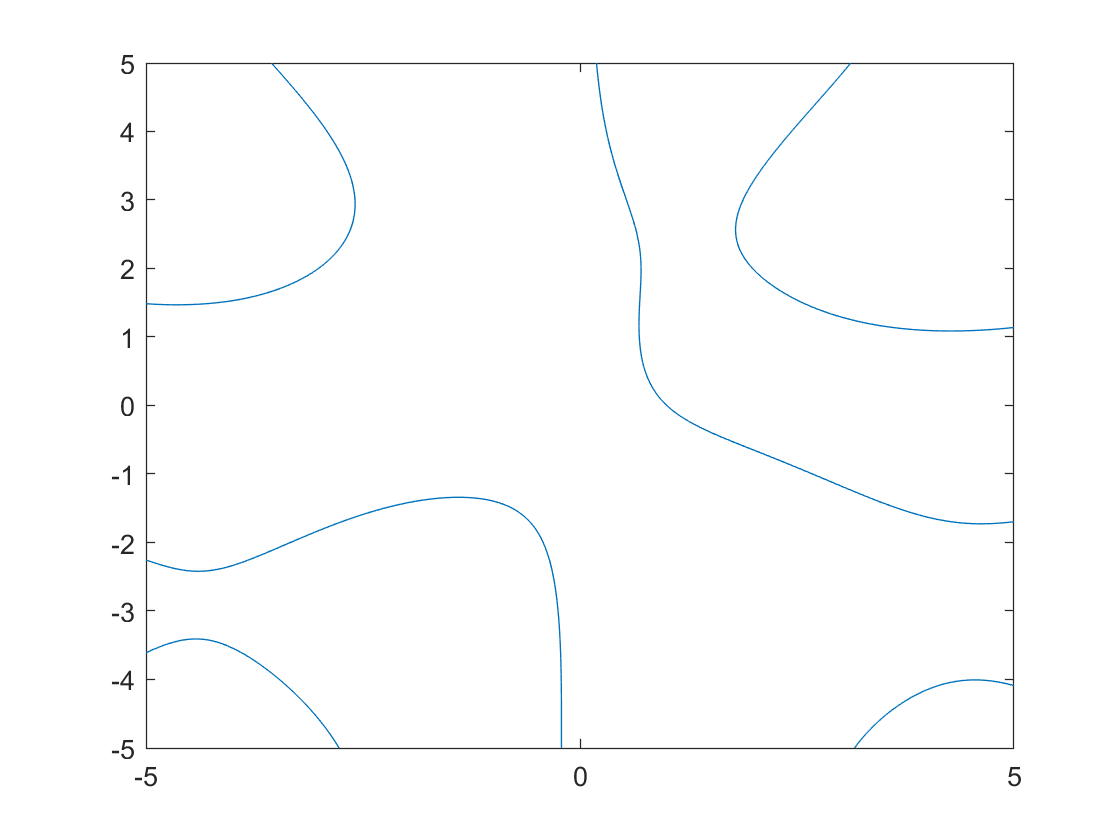

fimplicit(f1);

## Customizations

### Specify The Plot Axes Limits

Since the plot is implicitly defined from a function, the specified axes determine the size of the domain evaluated. The default domain spans $\left\lbrack -5,\;5\right\rbrack$ in $x\;$and $y\;$; however,  the $x\;$and $y$ limits can be redefined by passing a vector containing $\left\lbrack x_{\min } ,\;x_{\max } ,\;y_{\min } ,\;y_{\max } \right\rbrack$.

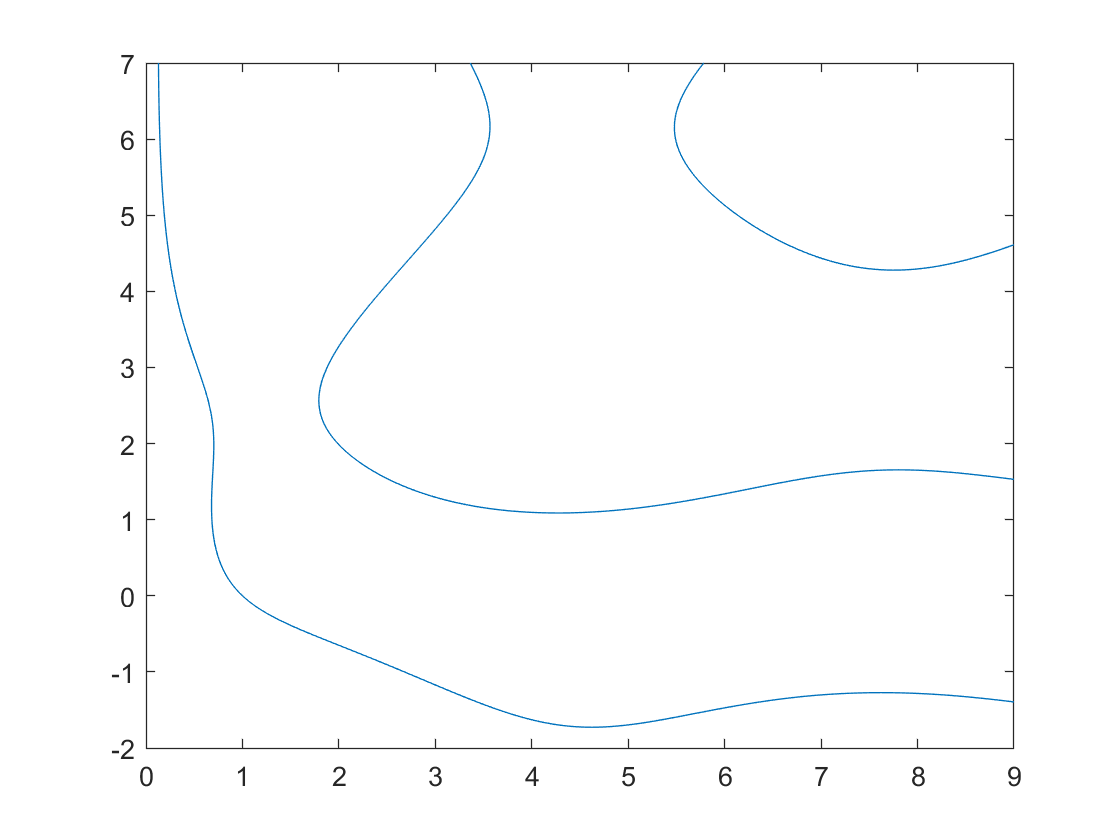

fimplicit(f1, [0 9 -2 7])

### Specify Line Options

The appearance of the plot can be modified by specifying various line properties. Line color, width, and style can all be manipulated by referencing the *LineWidth, Color, *and *LineStyle* properties with name-value pairings. Additionally, the x and y limits can be redefined by passing a vector containing $\left\lbrack x_{\min } ,\;x_{\max } ,\;y_{\min } ,\;y_{\max } \right\rbrack$

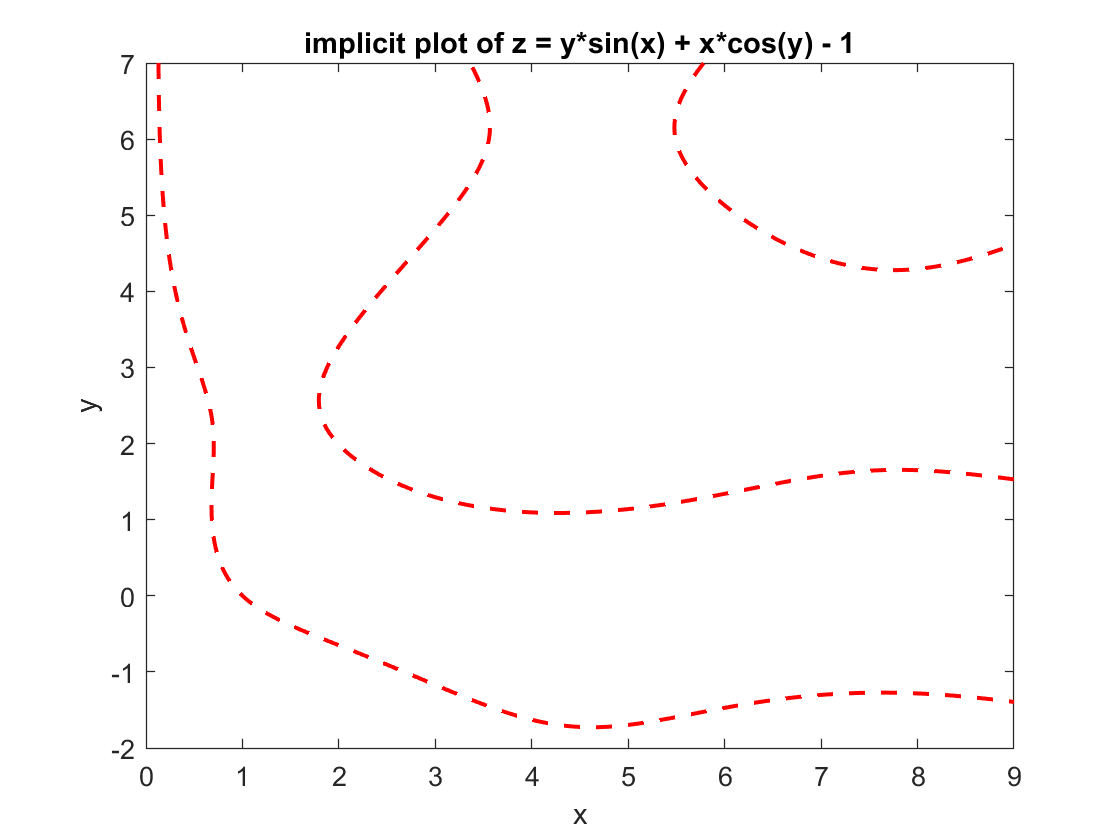

LineWidth = 1.5;
LineColor = 'r';
LineType = '--';

fm = fimplicit(f1, [0 9 -2 7],...
    "LineWidth", LineWidth,...
    "Color", LineColor,...
    "LineStyle", LineType);

title("implicit plot of z = y*sin(x) + x*cos(y) - 1")
xlabel('x')
ylabel('y')

## Additional Information

### Get All Area Properties

Graphics objects in MATLAB have many properties. To see all the properties of fimplicit, uncomment the following code

% get(fm)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[fimplicit](https://www.mathworks.com/help/matlab/ref/fimplicit.html)